close all;
clear all;

%% Load Data
load("data_save.mat");  % 'data' = [forcing_amp, forcing_freq, response_amp]

forcing_amp   = data(:, 1);  % dependent variable (what we predict)
forcing_freq  = data(:, 2);  % input
response_amp  = data(:, 3);  % input

X_data = [forcing_freq, response_amp]; % nx2
y_data = forcing_amp; %nx1

training_idx = randperm(length(y_data), 10)

training_idx =     37   276   291   320   390   429   335   253   402   251


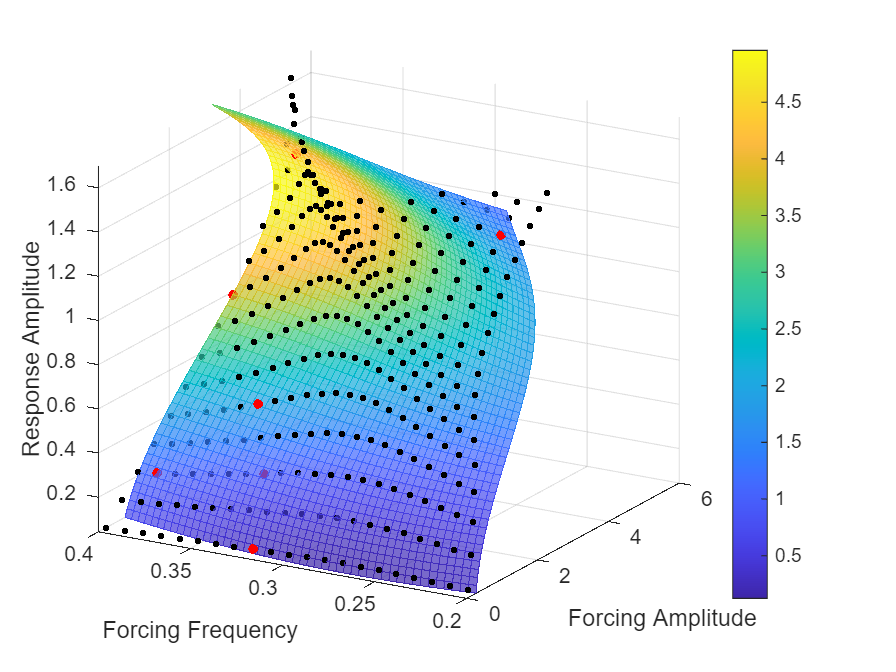

X_train = X_data(training_idx, :);
y_train = y_data(training_idx);

gpr_model = fitrgp(X_train, y_train, ...
    'KernelFunction', 'ardsquaredexponential', ...
    'Standardize', true);

%% Generate Prediction Grid
freq_range = linspace(min(forcing_freq), max(forcing_freq), 50);
resp_range = linspace(min(response_amp), 1.7, 50);
[FF, RR] = meshgrid(freq_range, resp_range);  % RR: response amp, FF: forcing freq

% Predict forcing amplitude
X_query = [FF(:), RR(:)];  % input = [response_amp, forcing_freq]

% query model
[Y_pred, Y_std] = predict(gpr_model, X_query);
AA = reshape(Y_pred, size(RR));     % Forcing amp surface
STD = reshape(Y_std, size(RR));     % Confidence surface

%% PLOT
figure; hold on; grid on;
xlabel("Forcing Amplitude"); ylabel("Forcing Frequency"); zlabel("Response Amplitude");
zlim([min(response_amp), 1.7]);
surf_opt = struct("CData", AA, "FaceAlpha",0.7, "EdgeColor","interp");
surf(AA, FF , RR, surf_opt)
colorbar
scatter3(forcing_amp, forcing_freq, response_amp, 10, "filled", "k")
scatter3(forcing_amp(training_idx), forcing_freq(training_idx), response_amp(training_idx), 20, "filled", "r")
view(-60, 20)

% --- Extract internals ---
Xraw   = gpr_model.X;                  % n×2 (raw inputs)
y      = gpr_model.Y;                  % n×1
beta   = gpr_model.Beta;               % constant mean
sigmaN = gpr_model.Sigma;              % noise std
theta  = gpr_model.KernelInformation.KernelParameters;
names  = gpr_model.KernelInformation.KernelParameterNames;

% Parse ARD params: length-scales then sigma_f (check order once)
% (Usually: names = {'LengthScale1','LengthScale2','SigmaF'})
D = size(Xraw,2);
ell    = theta(1:D)';                  % 1×2 length-scales
sigmaF = theta(end);                    % scalar amplitude

% Standardization (because you trained with 'Standardize',true)
loc  = gpr_model.PredictorLocation';     % 1×2
scale= gpr_model.PredictorScale';        % 1×2
Xs   = (Xraw - loc) ./ scale;           % standardized training inputs

% --- Kernel (ARD SE) helper (vectorized) ---
ardSE = @(A,B) sigmaF^2 * exp(-0.5*(((A(:,1)-B(:,1)')./ell(1)).^2 + ...
                                   ((A(:,2)-B(:,2)')./ell(2)).^2));

% Build K + noise and factorize once
K   = ardSE(Xs,Xs);
Kn  = K + (sigmaN^2)*eye(size(Xs,1));
L   = chol(Kn,'lower');
alpha = L'\(L\(y - beta));             % α = K_n^{-1}(y-β)

% --- Make a 2D grid in ORIGINAL units (u,v) ---
Xq_std = (X_query - loc) ./ scale;          % standardize test points
% Cross-covariances K(X, Xq)
Kxq = ardSE(Xs, Xq_std);               % n×m
% Mean and std at the grid
mu   = (Kxq' * alpha) + beta;          % m×1
W    = L \ Kxq;                         % n×m
varf = sigmaF^2 - sum(W.^2,1)';         % latent variance
varf = max(varf,0);                     % robustness avoid negative varf
stdy = sqrt(varf + sigmaN^2);           % predictive std of y
MU   = reshape(mu, size(RR));
STD  = reshape(stdy, size(RR));

% --- Gradient of the mean (vectorized) ---
% diffs per axis (n×m)
du = (Xs(:,1) - Xq_std(:,1)'); 
dv = (Xs(:,2) - Xq_std(:,2)');

% Sum_i α_i k_ij * (delta / ell^2)
Gux_std = sum( (alpha .* Kxq) .* (du / (ell(1)^2)), 1 )';   % m×1
Gvy_std = sum( (alpha .* Kxq) .* (dv / (ell(2)^2)), 1 )';   % m×1

% Chain rule back to ORIGINAL units (because x_std = (x - loc)/scale)
Gux = Gux_std ./ scale(1);             % ∂μ/∂u in original units
Gvy = Gvy_std ./ scale(2);             % ∂μ/∂v in original units
GX  = reshape(Gux, size(RR));
GY  = reshape(Gvy, size(RR));

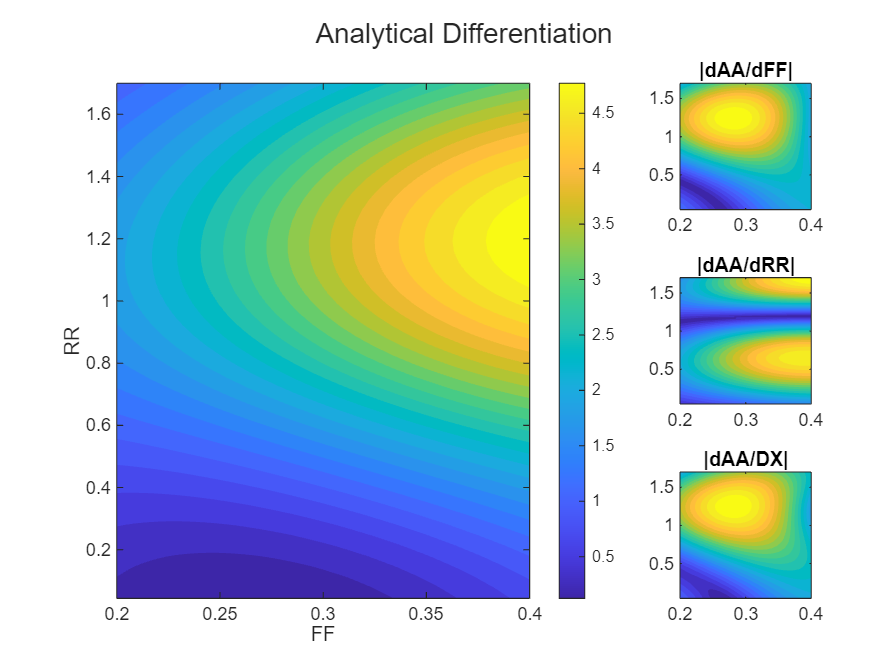

% --- Plots: mean + std with separate colorbars; quiver on mean ---
% Base contour on the main axes
t = tiledlayout(3, 3);
nexttile([3,2]);
contourf(FF, RR, MU, 25, 'LineStyle','none'); colorbar
xlabel('FF'); ylabel('RR');

nexttile(3);
contourf(FF, RR, abs(GX), 25, 'LineStyle','none');
title("|dAA/dFF|");
nexttile(6);
contourf(FF, RR, abs(GY), 25, 'LineStyle','none');
title("|dAA/dRR|");
nexttile(9);
contourf(FF, RR, hypot(GX, GY), 25, 'LineStyle','none');
title("|dAA/DX|")
title(t, "Analytical Differentiation")

## Bifurcation is when dAA/dRR == 0

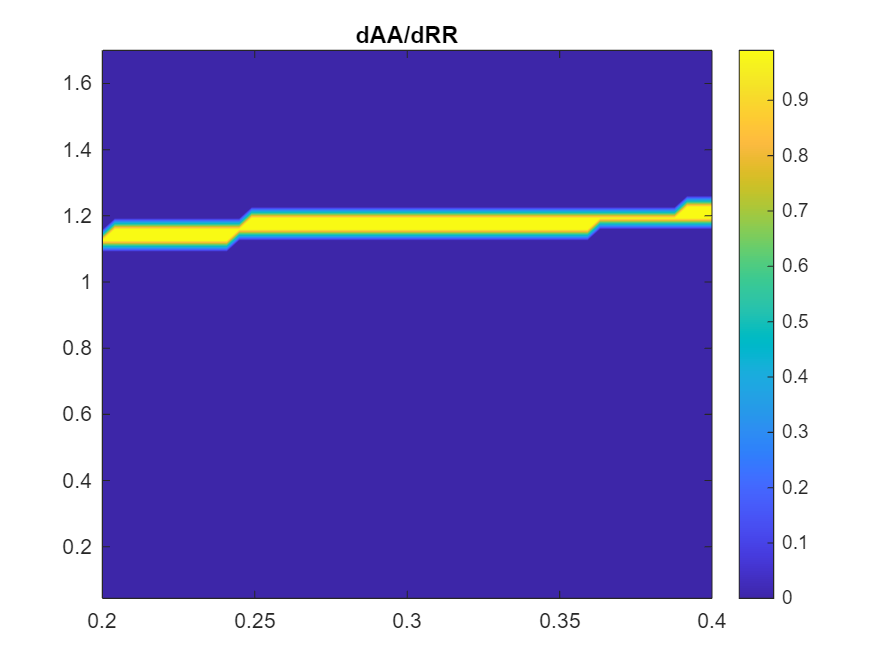

thresh_percent = 0.1;
thresh_value = thresh_percent.*max(abs(GY));

figure
contourf(FF, RR, abs(GY)<thresh_value, 100, 'LineStyle','none');
colorbar;
title("dAA/dRR");

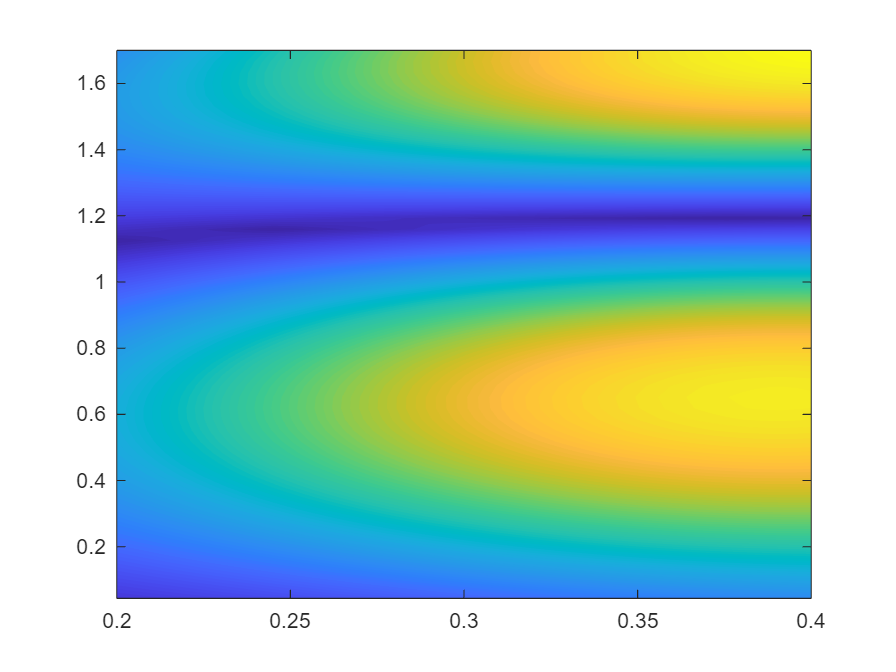

figure;
contourf(FF, RR, abs(GY), 100, 'LineStyle','none');